# 5. Arduino

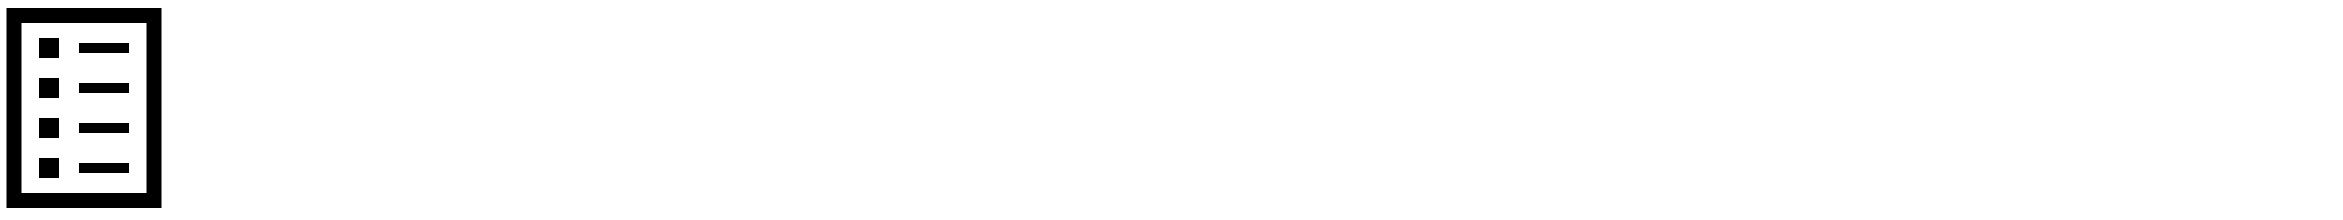

There are many built-in functions in Matlab to facilitate complex programming steps with few lines of code. Using built-in functions can save many hours of programming but also increases the amount that you must learn to master the language. There are common Matlab functions and also additional functions that are available as toolboxes. Many of the functions are also implemented as classes that are collections of objects and functions. To receive help on any function, type `help` with the function name. This module reviews the `arduino` functions for reading and writing to the microcontroller.

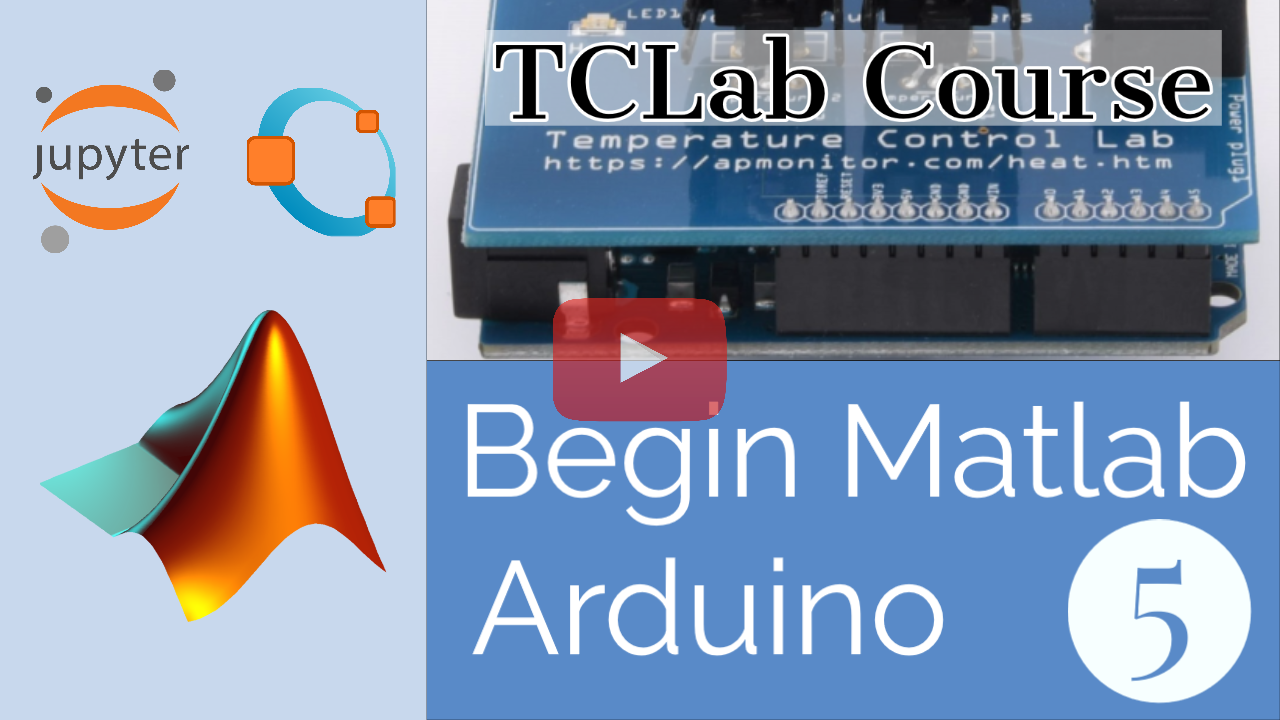

[Click here to watch the video: Matlab 👩‍💻 Arduino Leonardo](https://www.youtube.com/watch?v=4N_Zz-aUD4w)

### **One-Time Setup**

You may need to run `arduinosetup` from the command line before continuing with this section. The Arduino support package must also be installed. For `Matlab` you can access the Arduino support packages and instructions:

- [MATLAB Arduino support package](https://www.mathworks.com/hardware-support/arduino-matlab.html)

- [Simulink Arduino support package](https://www.mathworks.com/hardware-support/arduino-simulink.html)

For GNU Octave you can access instructions and the Arduino package from forge:

- [Octave Arduino support package](https://wiki.octave.org/Arduino_package).

After the Arduino support package is installed for either Matlab or Octave, you need to load the firmware on the Arduino once with the commands:

`    pkg` `load` `arduino`

`    arduinosetup`

There is a video on [Arduino setup with Matlab](https://youtu.be/DFvUJh8AYjE) and [Arduino setup with Octave](https://youtu.be/6UOn1IcNytA).

### **Try and Catch**

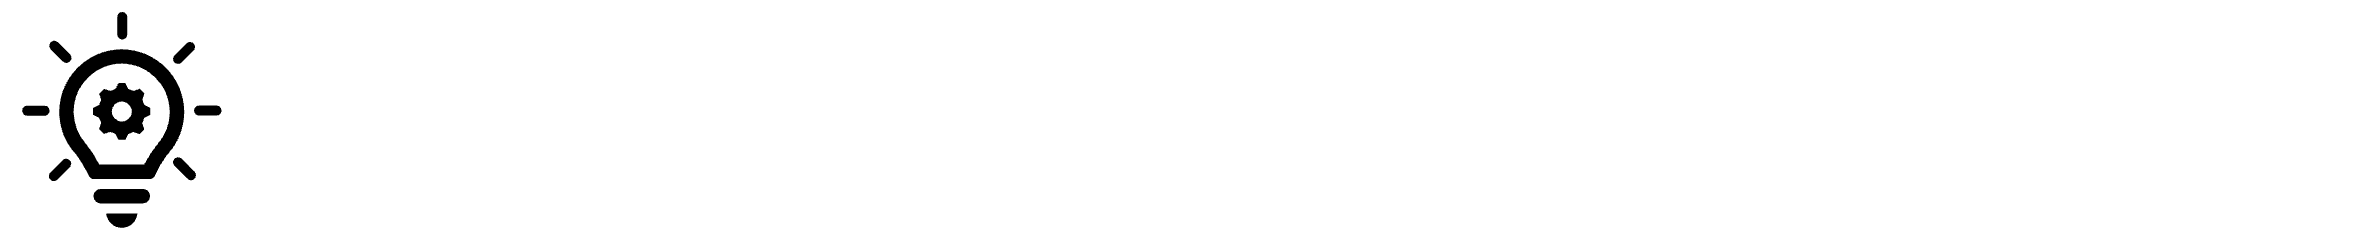

`Try` and `Catch` methods can catch program errors. The program attempts to run the code under `try`, and if it can't it runs the `catch` section of the code. This is useful in a number of situations, such as importing packages you may not have installed and printing a message that something is wrong.

try
    pkg load arduino
    disp('Loaded Arduino support package')
catch
    disp('Command not needed for Matlab. If Octave, need to install Arduino support package')
end

### **Objects**

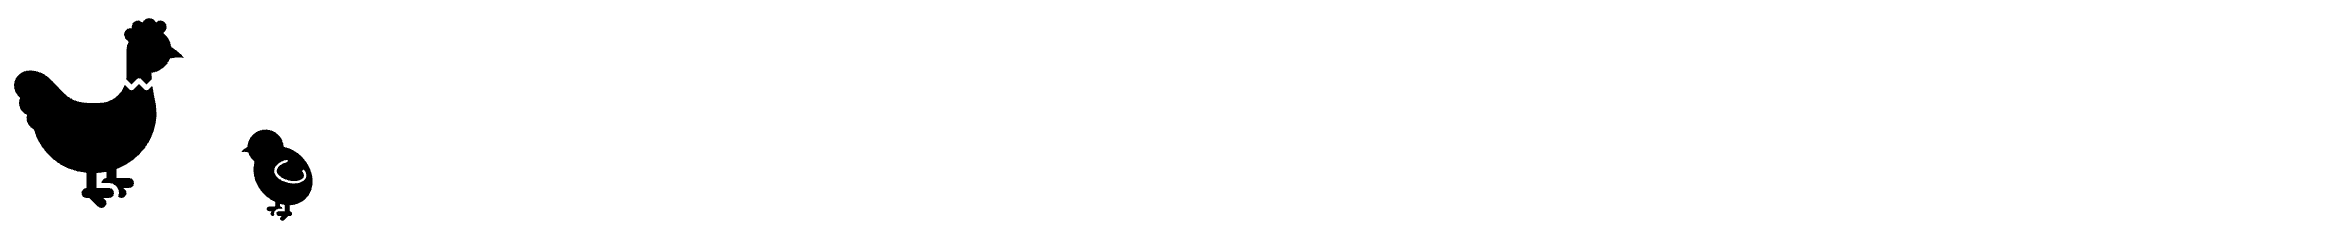

Variables may be `double` or `char` types or any type of object. Objects may also be created from a class (template) to create a new custom object. You use an assignment operator (`=`) to create an object and assign it to a name, such as `alab = arduino`. This is called a parent (`arduino`) to child (`alab`) relationship because `alab` is created from the class object `arduino`. The child object `alab` inherits all the functions of the parent. The child object is modified and customized in your code. You can give objects a name that you will remember and that are easy to type.

`    alab` `=` `arduino`

The first part of the expression is the child object name. For the Temperature Control Lab, we often use `lab` as the name of our object. In this case, we'll use the name `alab` as you first connect to the Arduino and access the raw signals. First, plug in the blue USB cable to the Arduino and your computer and connect to the arduino lab. If it does not complete this step then the firmware may not be loaded (see instructions above).

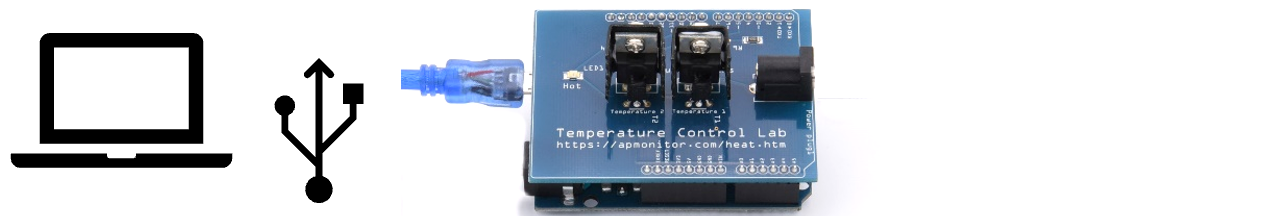

alab = arduino

If it connects successfully, you should see something like the following in Matlab or Octave:

**Matlab Successful Arduino Connection**

`    Port``:` `'COM10'`

                     `Board``:` `'Leonardo'`

             `AvailablePins``:` `{``'D2-D13'``,` `'A0-A5'``}`

      `AvailableDigitalPins``:` `{``'D2-D13'``,` `'A0-A5'``}`

          `AvailablePWMPins``:` `{``'D3'``,` `'D5-D6'``,` `'D9-D11'``,` `'D13'``}`

       `AvailableAnalogPins``:` `{``'A0-A5'``,` `'D4'``,` `'D6'``,` `'D8-D10'``,` `'D12'``}`

        `AvailableI2CBusIDs``:` `[``0``]`

`    AvailableSerialPortIDs``:` `[``1``]`

                 `Libraries``:` `{``'I2C'``,` `'SPI'``,` `'Servo'``}`

**Octave Successful Arduino Connection**

`alab` `=`

`    arduino` `object` `with` `fields` `of``:`

`        port` `=` `\\.\``COM10`    

`        board` `=` `leonardo`    

`        libraries` `=` `{`      

`            i2c`      

`            spi`      

`            servo`      

`            shiftregister`    

`        }`    

`        availablepins` `=` `{`      

`            d0` `-` `d17`      

`            a0` `-` `a5`      

`            d30`    

`        }`

The TCLab has two heaters (`D3` and `D5` pins), two temperature sensors (`A0` and `A2` pins), and an LED (`D9` pins).

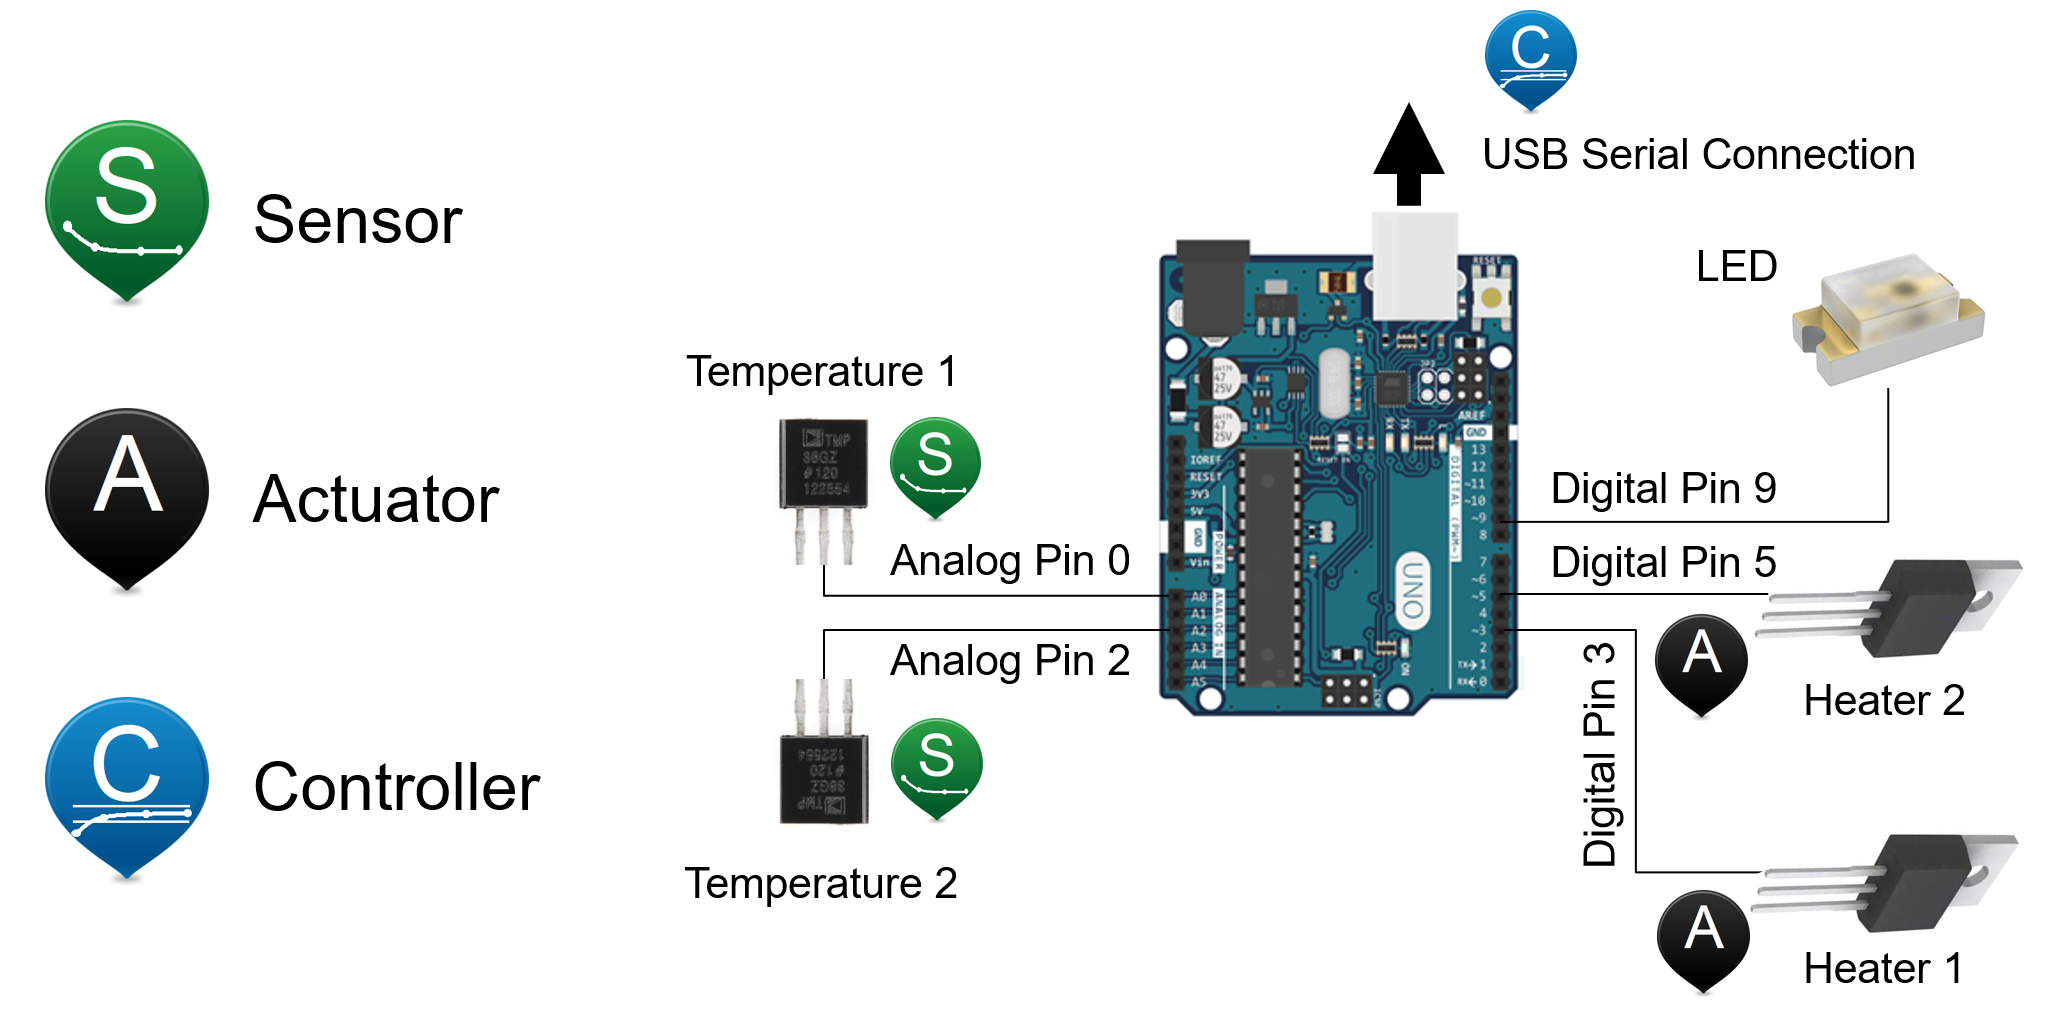

For the [Temperature Control Lab (TCLab)](https://apmonitor.com/heat.htm), the raw signals and commands are accessed from the following Arduino pins:

- ***A0***: Analog input 0 voltage to calculate temperature 1

- ***A2***: Analog input 2 voltage to calculate temperature 2

- ***D3***: Digital output 3 to adjust heater 1

- ***D5***: Digital output 5 to adjust heater 2

- ***D9***: Digital output 9 to adjust LED

The voltage from an Analog pin is read with `readVoltage(arduino_object,Pin)`. In this case, we'll start by reading from Analog pin 0 or `A0`.

v1 = readVoltage(alab,'A0');
disp(['Temperature 1 (Voltage): ', num2str(v1)])

For the TMP36 sensor, the relationship between voltage and temperature in °C is:


$$T = 100(V-0.5)$$


The temperature sensor is a transistor that can read temperatures between -40°C (0.1 V) and 150°C (2.0 V). Calculate the temperature from the voltage.

T1 = (v1 - 0.5)*100.0;
disp(['Temperature 1: ', num2str(T1), '°C'])

There is thermochromic paint on the heater that changes from *black* to *red* at 37°C to let you know when it is hot. Heat up the sensor with your finger on Temperature sensor 1 if it is cold. If it is hot then blow on the sensor to cool it off. Observe the change in temperature.

v1b = readVoltage(alab,'A0');
T1b = (v1b - 0.5)*100.0;
disp(['Temperature 1: ', num2str(T1), '°C'])
disp(['Temperature 1b: ', num2str(T1b), '°C'])
disp(['Temperature Change: ', num2str(T1b-T1), '°C'])

To control the LED, use the `writePWMDutyCycle()` function. This function sends a signal to a digital pin to turn on and off 490 times per second. If you give it a request of 1.0 then it is on constantly. With 0.0, it is always off and 0.5 means that it is on half of the cycles. Because it goes so fast, it appears that it is on only 50% even though it is cycling on and off rapidly.

writePWMDutyCycle(alab,'D9',0.5); disp('LED 50%')
pause(1)
writePWMDutyCycle(alab,'D9',0.3); disp('LED 30%')
pause(1)
writePWMDutyCycle(alab,'D9',0.1); disp('LED 10%')
pause(1)
writePWMDutyCycle(alab,'D9',0.02); disp('LED 2%')

Command not needed for Matlab. If Octave, need to install Arduino support package


Plug in the power cable and power supply to test the heaters. The power supply is required because the Arduino board cannot provide sufficient power for the heaters. The heater power is on a separate circuit that receives power from the white cable and power supply.

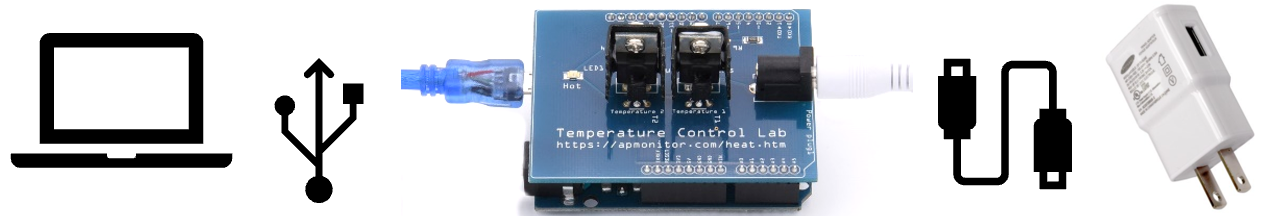

You can try plugging the white cable in to a computer's USB 2 port (0.5W) or USB 3 port (1.5W) but the white power supply (5V, 2A = 10W) provides the best power source. Note that using two USB ports on your computer for communication (blue cable) and power (white cable) can cause extra sensor noise because the heater PWM cycling interferes with the sensor readings. Using the white USB power supply is recommended.

Use the same `writePWMDutyCycle()` function but change `D9` to `D3` for heater 1 or `D5` for heater 2.

`    writePWMDutyCycle``(``alab``,``'D3'``,``0.6``)` `% Heater 1`

`    writePWMDutyCycle``(``alab``,``'D5'``,``0.2``)` `% Heater 2`

This turns on Heater 1 to 60%, waits 20 seconds, and then prints the before and after temperatures.

writePWMDutyCycle(alab,'D3',0.6); % Turn on Heater 1 to 60%
fprintf('Temperature 1: %0.2f°C\n', 100*(readVoltage(alab,'A0')-0.5))
disp('Wait 20 seconds')
pause(20)
fprintf('Temperature 1: %0.2f°C', 100*(readVoltage(alab,'A0')-0.5))
writePWMDutyCycle(alab,'D3',0.0); % Turn Off Heater 1

After you are done using the Arduino you can disconnect by clearing the Arduino object `alab`.

clear alab  % close connection

Cannot detect Arduino hardware. Make sure Arduino hardware is properly plugged in.

There is additional information on the TCLab in the following video and at [https://apmonitor.com/heat.htm](https://apmonitor.com/heat.htm), including use in Simulink, Java, and Python.

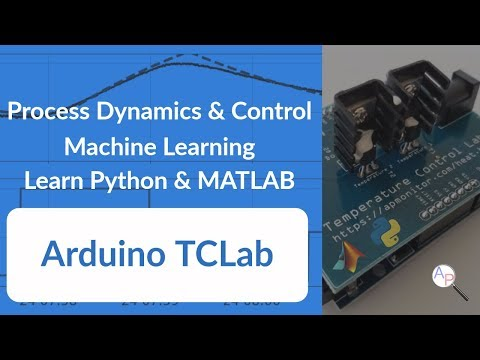

[Click here to watch the video: Arduino TCLab for Engineering Education](https://www.youtube.com/watch?v=E5747TUHVmQ)

**TCLab Test**

Download the `tclab.m` package by running the cell below (`Ctrl+Enter`). The `tclab.m` file will appear in the same folder where you are running this notebook. The source file `tclab.m` is from the [URL on GitHub](https://github.com/APMonitor/begin_matlab/blob/master/tclab.m) and may already be in your run directory. Matlab and Octave have different methods (`websave` or `urlwrite`) to retrieve an Internet file. We first `try` the Match function and then `catch` any errors by trying the Octave function.

file = 'tclab.m';
url = 'https://raw.githubusercontent.com/APMonitor/begin_matlab/master/tclab.m';

try   
    % for MATLAB    
    websave(file,url);
catch    
    % for Octave    
    urlwrite(url,file);
end

You can then connect to the TCLab (Arduino Leonardo) just like before but by creating a new `tclab` object.

`    lab` `=` `tclab`

The first part of the expression is the child object name. For the Temperature Control Lab, we often use `lab` to as the name of our object. For something like your incubator, you could make an object to connect with it, called something like `incubator`.

The second part after `=`, opens the object called `tclab`. This object is what allows you to connect with the TCLab, read current temperatures, adjust heaters, or change the LED brightness with simplified functions shown below.

**Connect**

`lab = tclab` Connect and create new lab object

lab = tclab; % Connect to the TCLab

**LED**

`lab.LED()` Percentage of output light for **Hot** light between 0 and 100%.

lab.LED(10);

**Heaters**

`lab.Q1()` and `lab.Q2()` Percentage of power to heaters between 0 and 100%.

lab.Q1(80);

**Temperatures**

`lab.T1` and `lab.T2` Value of current heater temperatures in degrees Celsius.

lab.T1lab.T2

**Shut down**

`lab.off()` turns off heaters.

lab.off()

**Disconnect**

`clear all` or `clear lab` to disconnect from lab.

clear lab % Close connection

### **Activity**

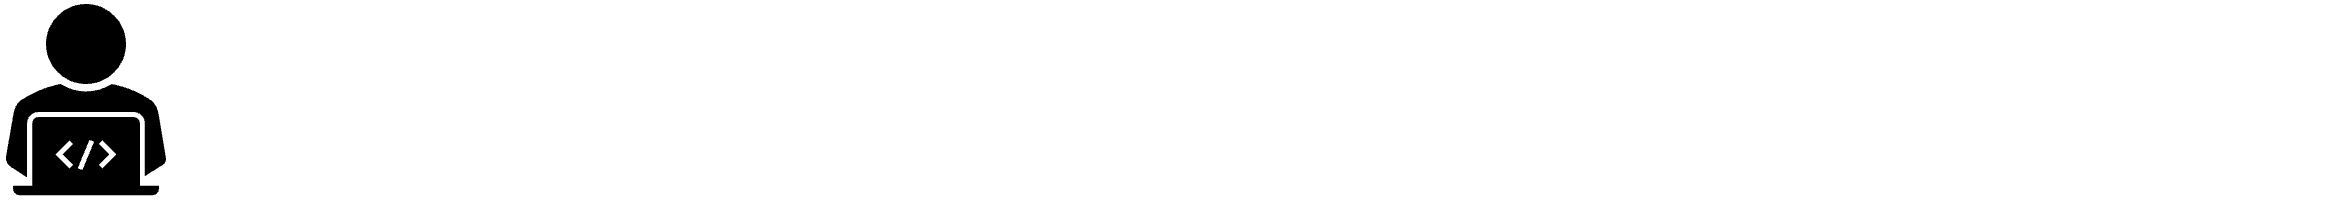

Connect the blue USB cable and plug in the white power cable to the power adapter. Run the TCLab exercise below that imports and tests the `TCLab` functions.

- Modify the name of the object from `lab` to `inc` (for incubator)

- Add comments to the code such as `% this is a comment` on the purpose of each line

- Change the LED brightness to the same level as the temperature to visually display `T1`

**TCLab Function Help**

***Connect:*** `lab = tclab` Connect and create new lab object.

***LED:*** `lab.LED()` Percentage of output light for **Hot** Light.

***Heaters:*** `lab.Q1()` and `lab.Q2()` Percentage of power to heaters (0-100).

***Temperatures:*** `lab.T1` and `lab.T2` Value of current heater temperatures.

***Disconnect:*** `lab.off()` turns off LED and heaters, `clear lab` disconnects lab.

clear lab
lab = tclab;
disp('Turn on heaters and LED for 10 seconds')
lab.Q1(100);
lab.LED(100);

fprintf('T1: %.2f \n',lab.T1)
pause(10);
fprintf('T1: %.2f \n',lab.T1)

lab.off;
clear lab